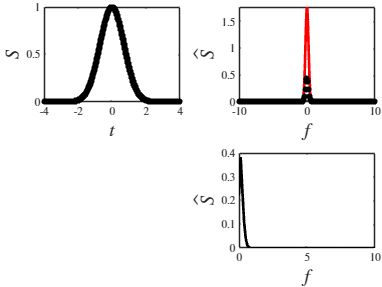


% Obtain the Fourier transform of various signals analytically 
% and numerically

clear all; close all; clc;

% These lines change all interpreters to latex. 
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

%% Contiuous representation
syms S t f

% infinity bound integral test
% test_val = int(exp(-t^2),-inf,inf)

my_exp = exp(-1i * 2 * pi * f * t);

% Gaussian function
S = exp(-t^2);
tlim = [-4,4];
flim = [-10,10];
ilim = [-inf,inf];

% % sinusoidal function
% S = 1.7+0.3*cos(4*pi*t);
% tlim = [-4,4];
% flim = [-6,6];
% ilim = [-4,4];

% % triangle function
% S = 1-abs(t);
% tlim = [-3,3];
% flim = [-2,2];
% ilim = [-3,3];

S_hat = eval(int( S*my_exp, 't', ilim(1), ilim(2)));


%% Discrete representation
N = 512;
t_d = linspace(tlim(1),tlim(2),N);
S_d = double(subs(S,t_d));

% Sampling period
T = t_d(2)-t_d(1);
% Sampling frequency
Fs = 1/T;
% number of samples (signal length)
L = length(S_d);
% frequency array
f_d = Fs/L*(-L/2:L/2-1);  
% Scaled complex amplitude array
S_hat_d_scaled = fftshift(fft(S_d));
% Absolute value of the unscaled amplitude array
S_hat_d = abs(S_hat_d_scaled) / L * 2;

% single sided spectrum
f_d_SiSi = Fs/L*(0:(L/2));
S_FFT_abs = abs(fft(S_d)/L);
S_hat_d_SiSi = S_FFT_abs(1:L/2+1);
S_hat_d_SiSi(2:end-1) = 2*S_hat_d_SiSi(2:end-1);



%% Plotting
figure;
set(gcf, 'Units', 'pixels', 'Position', [100, 100, 1600/2, 1200/2]); % Set figure size to 180mm x 100mm

% Define paper size for PDF export
% set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperSize', [16 12]);    % Set paper size to 16 cm x 12 cm for PDF

% Use tiledlayout for more control over subplot spacing
my_layout = tiledlayout(2, 2, 'Padding', 'tight', 'TileSpacing', 'compact');

% First subplot - Sine Wave
ax1 = nexttile;
fplot(t,S,tlim,'-r','LineWidth',2)
hold on
plot(t_d,S_d,'.k','MarkerSize',14)
xlabel('$t$',FontSize=14)
ylabel('$S$',FontSize=14)

ax2 = nexttile;
fplot(f,abs(S_hat),flim,'-r','LineWidth',2)
hold on
plot(f_d, S_hat_d,'.k','MarkerSize',14)
xlim([flim(1),flim(2)])
xlabel('$f$',FontSize=14)
ylabel('$\hat S$',FontSize=14)

nexttile;
ax4 = nexttile;
plot(f_d_SiSi,S_hat_d_SiSi,'-k','LineWidth',2)
xlim([0,flim(2)])
xlabel('$f$',FontSize=14)
ylabel('$\hat S$',FontSize=14)

delete(nexttile(3));


disp([max(S_hat_d), trapz(t_d,S_d)])

    0.4422    1.7725

